# Data preparation

## Load the data

We load the original dataset in '../RobotPdMDataset', and create two cell arrays:

- X: A cellarray of 2000 elements, each element is a 1000*6 matrix, that contains the x, y, z coordiates of the desired and response trajectories, respetively.

- y: A cellarray of 2000 elements, each element is the label (str).

clear; clc; close all;

% Set random seed for reproduction purpose.
rng(100);

% Define the path to check for 'conc_dataset.mat'
datasetPath = fullfile('..', 'RobotPdMDataset', 'conc_dataset.mat');

% Check if the file exists
if isfile(datasetPath)
    % If the file exists, load the dataset
    load(datasetPath, 'X', 'y');
    disp('Loaded data from conc_dataset.mat.');
else
    % If the file does not exist, run read_original_data
    mainFolder = '../RobotPdMDataset';  % Or use the correct path
    [X, y] = read_original_data(mainFolder);
    
    % Save X and y as 'conc_dataset.mat' under '../RobotPdMDataset'
    save(datasetPath, 'X', 'y');
    disp('Data generated and saved as conc_dataset.mat.');
end

Loaded data from conc_dataset.mat.


## Training and validation set creation

We randomly split a dataset and train a LSTM.

% Shuffle the dataset using the cvpartition function
training_ratio = .9;
n_dataset = numel(X);
training_size = floor(training_ratio*n_dataset);
cvObj = cvpartition(y, 'HoldOut', training_size);
idx = cvObj.test;

% Split into training and test data based on training size specified
X_train = X(idx');
X_test = X(~idx');
y_train = categorical(y(idx'));
y_test = categorical(y(~idx'));

We can show the distribution of classes in the training and testing dataset, to make sure the seperation is fair.

summary(y_train);

     Healthy      Motor_1_Stuck      Motor_2_Stuck      Motor_3_Stuck      Motor_4_Stuck 
     360          360                360                360                360           


summary(y_test);

     Healthy      Motor_1_Stuck      Motor_2_Stuck      Motor_3_Stuck      Motor_4_Stuck 
     40           40                 40                 40                 40            


# Pre-processing and feature engineering

In this section, we preprocess the data and augument the dataset by adding some new features from feature engineering.

% Add an additional feature of the residual.
for index = 1:numel(X_train)
    tmp = X_train{index};
    residual = tmp(:, 1:3) - tmp(:, 4:6);
    tmp(:, 4:6) = residual;
    X_train{index} =  tmp;
end

for index = 1:numel(X_test)
    tmp = X_test{index};
    residual = tmp(:, 1:3) - tmp(:, 4:6);
    tmp(:, 4:6) = residual;
    X_test{index} =  tmp;
end

## Normalize Training Features

Networks will often train better when normalized. Calculate the mean and standard deviation and normalize each element of the training feature set. 

X_train = normalize_features(X_train);
X_test = normalize_features(X_test);

# Training and evaluating the model

Use an LSTM network. An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first lstmlayer will have 100 hidden units and output the sequence data. Then a dropout layer will be used to reduce probability of overfitting. The second lstmlayer will output just the last step of the time sequence.

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

## Define Network Hyperparameters

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",50, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_test, y_test}, ...
    'ValidationFrequency',validationFrequency);

## Train The Network

This network takes about 100 seconds to train on an NVIDIA RTX 2080 GPU.

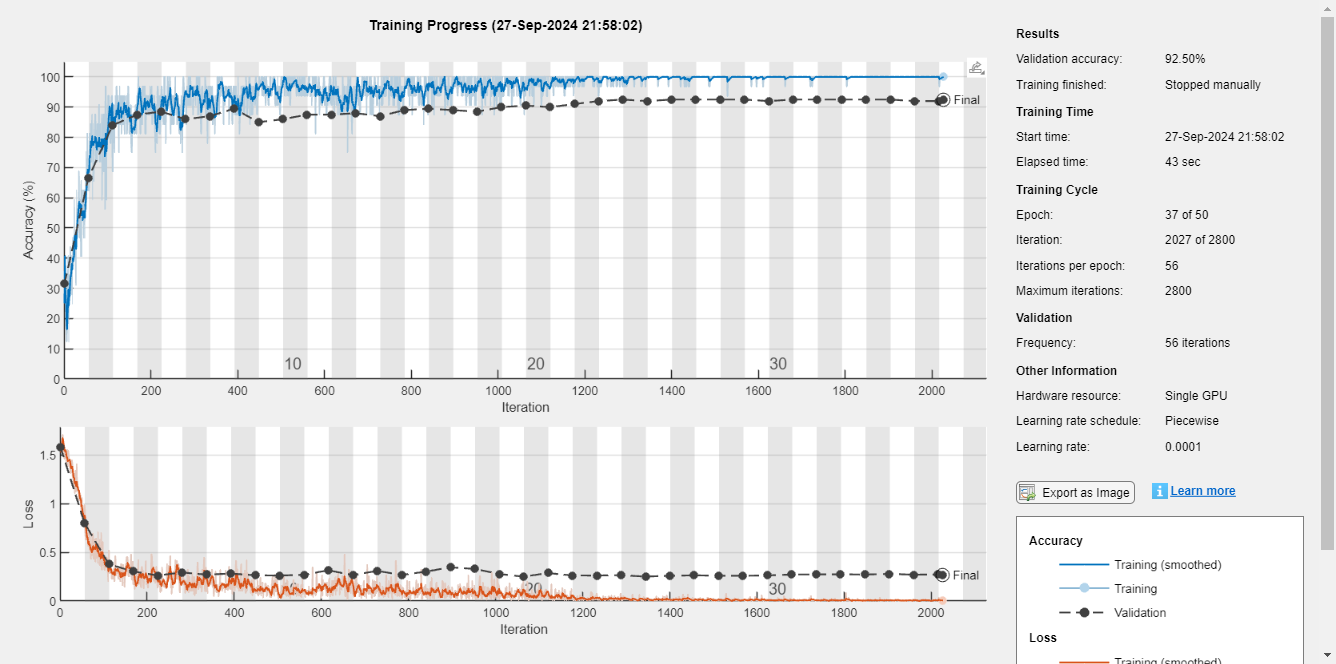

doTraining = true;

if doTraining
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save('diagnosisNet.mat', 'diagnosisNet');
else

    load('diagnosisNet.mat', 'diagnosisNet');
end

## Test The Network

Now that the network has been trained, we can test it on the validation data. 

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

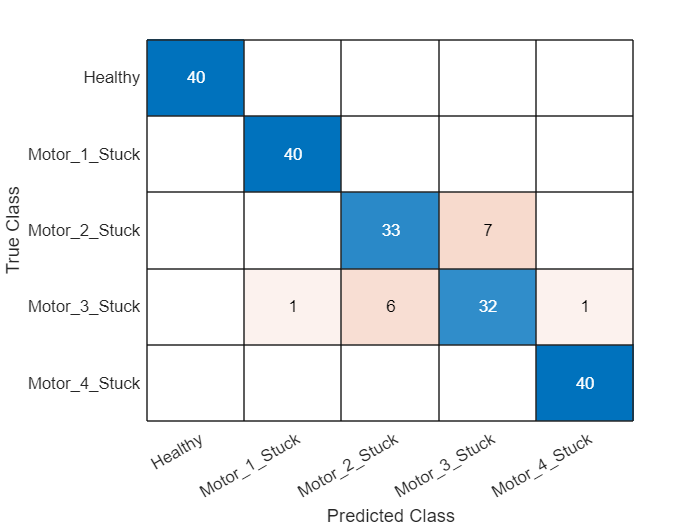

cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = eval_perf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 92.50%


class_names = categories(y_test);
for i = 1:numClasses
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = 1.00, Recall = 1.00, F1 Score = 1.00
Class 2 (Motor_1_Stuck): Precision = 0.98, Recall = 1.00, F1 Score = 0.99
Class 3 (Motor_2_Stuck): Precision = 0.85, Recall = 0.82, F1 Score = 0.84
Class 4 (Motor_3_Stuck): Precision = 0.82, Recall = 0.80, F1 Score = 0.81
Class 5 (Motor_4_Stuck): Precision = 0.98, Recall = 1.00, F1 Score = 0.99


# Supporting functions

function [X_shuffled, y_shuffled] = read_original_data(mainFolder)
    % This function reads the original data under path mainFolder. 
    % It will shuffle the data, and create X and y for training the
    % network.

    % Get the list of all subfolders
    subFolders = dir(mainFolder);
    subFolders = subFolders([subFolders.isdir]);  % Filter only directories
    subFolders = subFolders(~ismember({subFolders.name}, {'.', '..'})); % Remove '.' and '..'
    
    % Count how many dataset we have.
    n_dataset = 0;
    for i = 1:length(subFolders)
        % Locate the sub dictionary.
        folderPath = fullfile(mainFolder, subFolders(i).name);    
        % Get a list of all .mat files in the subfolder that start with 'dataset_'
        matFiles = dir(fullfile(folderPath, 'dataset_*.mat'));
        for j = 1:length(matFiles)
            n_dataset = n_dataset + 1;
        end
    end
    
    % Initialize cell array for data and cell array for labels
    X = cell(1, n_dataset);
    y = cell(1, n_dataset);
    
    % Iterate over each subfolder to retrieve the data.
    pointer = 0;
    for i = 1:length(subFolders)
        % Locate the sub dictionary.
        folderPath = fullfile(mainFolder, subFolders(i).name);    
        % Get a list of all .mat files in the subfolder that start with 'data_'
        matFiles = dir(fullfile(folderPath, 'dataset_*.mat'));
        
        % Loop through each valid .mat file
        for j = 1:length(matFiles)
            matFilePath = fullfile(folderPath, matFiles(j).name);
            
            % Load the .mat file
            loadedData = load(matFilePath);
            
            % Assuming the data is stored in a variable named 'data'
            % Adjust this if the variable name is different
            dataMatrix = loadedData.dataset;
            
            % Append the loaded data to the cell array X
            pointer = pointer + 1;
            X{pointer} = dataMatrix;
            
            % Append the subfolder name as the label to y
            y{pointer} = subFolders(i).name;
        end
    end
    
    % Shuffle data.
    % Get the number of elements in X (or y, since they are of the same length)
    numElements = numel(X);
    % Generate a random permutation of indices from 1 to numElements
    randomOrder = randperm(numElements);
    % Shuffle X and y using the random permutation
    X_shuffled = X(randomOrder);
    y_shuffled = y(randomOrder);
end


function X = normalize_features(X)
    % This function normalizes the features.
    % Input: X is an cell array of 1*n_data, whose elements are matrixs of
    % (n_seq, n_features).

    % Concatenate all the features. Creat a matrix of (n_seq*n_data,
    % n_features).
    allFeatures = cat(1, X{:});

    % Do the normalization.
    M = mean(allFeatures);
    S = std(allFeatures);
    
    for index = 1:numel(X)
       X{index} =  ((X{index} - M)./S);
    end
end


function [accuracy, precision, recall, f1Score] = eval_perf(y_test, y_pred)
    % Return the accuracy of a multi-class classificaiton problem.
    % Return also the precision, recall and f1 score for each class.
    confMat = confusionmat(y_test, y_pred);
    
    % Initialize vectors to store precision, recall, F1 score for each class
    numClasses = size(confMat, 1); % Number of classes
    precision = zeros(numClasses, 1);
    recall = zeros(numClasses, 1);
    f1Score = zeros(numClasses, 1);
    
    % Calculate accuracy
    accuracy = sum(diag(confMat)) / sum(confMat(:));
    
    % Loop over each class to calculate precision, recall, and F1 score
    for i = 1:numClasses
        TP = confMat(i, i);  % True Positives for class i
        FP = sum(confMat(:, i)) - TP;  % False Positives for class i
        FN = sum(confMat(i, :)) - TP;  % False Negatives for class i
    
        % Precision = TP / (TP + FP)
        precision(i) = TP / (TP + FP);
    
        % Recall = TP / (TP + FN)
        recall(i) = TP / (TP + FN);
    
        % F1 Score = 2 * (precision * recall) / (precision + recall)
        f1Score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
    end
end